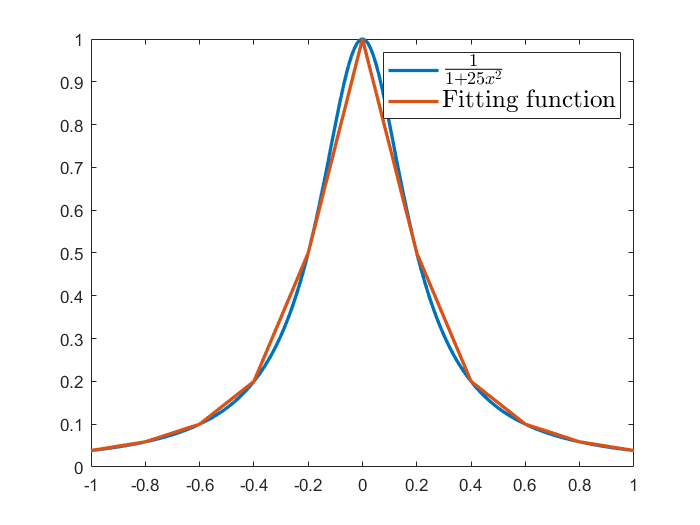

clc,clear,close all
x = -1:0.01:1;
y = 1./(1+25*x.^2);
plot(x,y,'LineWidth',2)
hold on

x = -1:0.2:1;
y = 1./(1+25*x.^2);
plot(x,y,'LineWidth',2)
hold off
h = legend('$\frac{1}{1+25x^2}$','Fitting function');
set(h,'Interpreter','latex','FontName','Times New Roman','FontSize',15,'FontWeight','normal') %设置legend为latex解释器显示分式


t = x;
syms x;
int_y = 0

int_y = 0

for i = 1:length(t)-1
    f = (y(i+1)-y(i))/(t(i+1)-t(i))*(x-t(i)) + y(i)
    int_y = subs(int_y,x,t(i));
    int_y = int_y+int(f,t(i),x);
    disp(['当 x 属于[',num2str(t(i)),',',num2str(t(i+1)),']时，积分公式为'])
    disp(int_y)
end

$$f = \frac{45\,x}{442}+\frac{31}{221}$$

当 x 属于[-1,-0.8]时，积分公式为


$$\frac{\left(45\,x+79\right)\,\left(x+1\right)}{884}$$

$$f = \frac{7\,x}{34}+\frac{19}{85}$$

当 x 属于[-0.8,-0.6]时，积分公式为


$$\frac{\left(5\,x+4\right)\,\left(35\,x+48\right)}{1700}+\frac{43}{4420}$$

$$f = \frac{x}{2}+\frac{2}{5}$$

当 x 属于[-0.6,-0.4]时，积分公式为


$$\frac{\left(5\,x+3\right)\,\left(x+1\right)}{20}+\frac{283}{11050}$$

$$f = \frac{3\,x}{2}+\frac{4}{5}$$

当 x 属于[-0.4,-0.2]时，积分公式为


$$\frac{\left(3\,x+2\right)\,\left(5\,x+2\right)}{20}+\frac{1229}{22100}$$

$$f = \frac{5\,x}{2}+1$$

当 x 属于[-0.2,0]时，积分公式为


$$\frac{\left(5\,x+1\right)\,\left(5\,x+3\right)}{20}+\frac{694}{5525}$$

$$f = 1-\frac{5\,x}{2}$$

当 x 属于[0,0.2]时，积分公式为


$$\frac{6091}{22100}-\frac{x\,\left(5\,x-4\right)}{4}$$

$$f = \frac{4}{5}-\frac{3\,x}{2}$$

当 x 属于[0.2,0.4]时，积分公式为


$$\frac{4703}{11050}-\frac{\left(5\,x-1\right)\,\left(15\,x-13\right)}{100}$$

$$f = \frac{2}{5}-\frac{x}{2}$$

当 x 属于[0.4,0.6]时，积分公式为


$$\frac{10953}{22100}-\frac{\left(5\,x-2\right)\,\left(5\,x-6\right)}{100}$$

$$f = \frac{19}{85}-\frac{7\,x}{34}$$

当 x 属于[0.6,0.8]时，积分公式为


$$\frac{2904}{5525}-\frac{\left(5\,x-3\right)\,\left(7\,x-11\right)}{340}$$

$$f = \frac{31}{221}-\frac{45\,x}{442}$$

当 x 属于[0.8,1]时，积分公式为


$$\frac{11967}{22100}-\frac{\left(5\,x-4\right)\,\left(45\,x-88\right)}{4420}$$

int_y = subs(int_y,x,t(i));
disp('利用该公式计算得到积分为')

利用该公式计算得到积分为


disp(vpa(int_y,4))

$$0.5415$$

disp('实际积分值为')

实际积分值为


syms x
f = 1./(1+25*x.^2);
vpa(int(f,x,-1,1),4)

$$ans = 0.5494$$